%setting up different not used variables
syms x K ss omeg

%The transferfunction form we are looking for, omeg = omega and ss=s
K/(ss^2+omeg^2)

$$ans = \frac{K}{{\mathrm{omeg}}^{2}+{\mathrm{ss}}^{2}}$$


%Data matrix
A= [0.75,0.75,0.75,0.75,0.75,0.75,0.75,0.76,0.76,0.76,0.75,0.76,0.75,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.75,0.75,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.76,0.75,0.75,0.76,0.75,0.75,0.76,0.75,0.75,0.75,0.75,0.75,0.75,0.75,0.75,0.75,0.77,0.82,0.89,0.99,1.1,1.22,1.37,1.51,1.68,1.82,1.96,2.09,2.2,2.29,2.36,2.4,2.43,2.42,2.39,2.34,2.27,2.18,2.08,1.97,1.83,1.71,1.59,1.46,1.34,1.23,1.15,1.08,1.02,0.99,0.98,0.99,1.02,1.08,1.15,1.23,1.32,1.43,1.54,1.65,1.76,1.86,1.96,2.04,2.11,2.16,2.2,2.23,2.23,2.2,2.18,2.12,2.06,1.99,1.9,1.81,1.72,1.62,1.52,1.44,1.36,1.28,1.23,1.2,1.17,1.16,1.17,1.2,1.24,1.29,1.35,1.42,1.5,1.58,1.66,1.74,1.82,1.89,1.94,2,2.03,2.07,2.07,2.06,2.06,2.02,1.99,1.93,1.88,1.82,1.76,1.69,1.62,1.56,1.49,1.43,1.39,1.36,1.33,1.32,1.32,1.33,1.34,1.38,1.42,1.47,1.51,1.57,1.63,1.68,1.73,1.79,1.84,1.87,1.89,1.91,1.91,1.93,1.91,1.89,1.87,1.83,1.79,1.75,1.7,1.66,1.62,1.58,1.54,1.51,1.49,1.47,1.46,1.46,1.47,1.48,1.49,1.51,1.54,1.57,1.6,1.63,1.66,1.69,1.72,1.75,1.76,1.78,1.8,1.8,1.8,1.81,1.79,1.79,1.76,1.76,1.74,1.71,1.7,1.67,1.65,1.64,1.62,1.6,1.59,1.59,1.58,1.58,1.58,1.59,1.59,1.6,1.61,1.61,1.63,1.64,1.65,1.66,1.68,1.68,1.69,1.7,1.7,1.7,1.71,1.7,1.7,1.7,1.69,1.68,1.67,1.68,1.67,1.67,1.66,1.66,1.65,1.65,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.67,1.67,1.66,1.67,1.66,1.66,1.66,1.67,1.67,1.67,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.67,1.66,1.67,1.67,1.66,1.67,1.67,1.66,1.66,1.66,1.65,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.67,1.67,1.66,1.66,1.66,1.67,1.67,1.66,1.66,1.66,1.66,1.67,1.65,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.67,1.66,1.66,1.67,1.67,1.66,1.66,1.66,1.66,1.67,1.67,1.67,1.66,1.67,1.66,1.66,1.66,1.67,1.66,1.66,1.65,1.67,1.66,1.66,1.66,1.66,1.67,1.67,1.66,1.67,1.67,1.66,1.67,1.66,1.66,1.67,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.67,1.66,1.67,1.66,1.67,1.66,1.66,1.65,1.66,1.66,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.67,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.66,1.67,1.67,1.67,1.67,1.67,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.66,1.67,1.66,1.67,1.66,1.66,1.66,1.66,1.67,1.67,1.67,1.66,1.68,1.67];
A'

ans =     0.7500
    0.7500
    0.7500
    0.7500
    0.7500
    0.7500
    0.7500
    0.7600
    0.7600
    0.7600


%Time matrix
Time= [1,21,41,61,81,101,121,141,161,181,201,221,241,261,281,301,321,341,361,381,401,421,441,461,481,501,521,541,561,581,601,621,641,661,681,701,721,741,761,781,801,821,841,861,881,901,921,941,961,981,1001,1042,1062,1082,1102,1122,1142,1162,1182,1202,1222,1242,1262,1282,1302,1322,1342,1362,1382,1402,1422,1442,1462,1482,1502,1522,1542,1562,1582,1602,1622,1642,1662,1682,1702,1722,1742,1762,1782,1802,1822,1842,1862,1882,1902,1922,1942,1962,1982,2002,2022,2042,2062,2082,2102,2122,2142,2162,2182,2202,2222,2242,2262,2282,2302,2322,2342,2362,2382,2402,2422,2442,2462,2482,2502,2522,2542,2562,2582,2602,2622,2642,2662,2682,2702,2722,2742,2762,2782,2802,2822,2842,2862,2882,2902,2922,2942,2962,2982,3002,3022,3042,3062,3082,3102,3122,3142,3162,3182,3202,3222,3242,3262,3282,3302,3322,3342,3362,3382,3402,3422,3442,3462,3482,3502,3522,3542,3562,3582,3602,3622,3642,3662,3682,3702,3722,3742,3762,3782,3802,3822,3842,3862,3882,3902,3922,3942,3962,3982,4002,4022,4042,4062,4082,4102,4122,4142,4162,4182,4202,4222,4242,4262,4282,4302,4322,4342,4362,4382,4402,4422,4442,4462,4482,4502,4522,4542,4562,4582,4602,4622,4642,4662,4682,4702,4722,4742,4762,4782,4802,4822,4842,4862,4882,4902,4922,4942,4962,4982,5002,5022,5042,5062,5082,5102,5122,5142,5162,5182,5202,5222,5242,5262,5282,5302,5322,5342,5362,5382,5402,5422,5442,5462,5482,5502,5522,5542,5562,5582,5602,5622,5642,5662,5682,5702,5722,5742,5762,5782,5802,5822,5842,5862,5882,5902,5922,5942,5962,5982,6002,6022,6042,6062,6082,6102,6122,6142,6162,6182,6202,6222,6242,6262,6282,6302,6322,6342,6362,6382,6402,6422,6442,6462,6482,6502,6522,6542,6562,6582,6602,6622,6642,6662,6682,6702,6722,6742,6762,6782,6802,6822,6842,6862,6882,6902,6922,6942,6962,6982,7002,7022,7042,7062,7082,7102,7122,7142,7162,7182,7202,7222,7242,7262,7282,7302,7322,7342,7362,7382,7402,7422,7442,7462,7482,7502,7522,7542,7562,7582,7602,7622,7642,7662,7682,7702,7722,7742,7762,7782,7802,7822,7842,7862,7882,7902,7922,7942,7962,7982,8002,8022,8042,8062,8082,8102,8122,8142,8162,8182,8202,8222,8242,8262,8282,8302,8322,8342,8362,8382,8402,8422,8442,8462,8482,8502,8522,8542,8562,8582,8602,8622,8642,8662,8682,8702,8722,8742,8762,8782,8802,8822,8842,8862,8882,8902,8922,8942,8962,8982,9002,9022,9042,9062,9082,9102,9122,9142,9162,9182,9202,9222,9242,9262,9282,9302,9322,9342,9362,9382,9402,9422,9442,9462,9482,9502,9522,9542,9562,9582,9602,9622,9642,9662,9682,9702,9722,9742,9762,9782,9802,9822,9842,9862,9882,9902,9922,9942,9962,9982,10002];
Time'

ans =      1
    21
    41
    61
    81
   101
   121
   141
   161
   181


%Relation between volt and angle
VoltToAngle = 45.*(1.-A'*2./3.3)

VoltToAngle =    24.5455
   24.5455
   24.5455
   24.5455
   24.5455
   24.5455
   24.5455
   24.2727
   24.2727
   24.2727


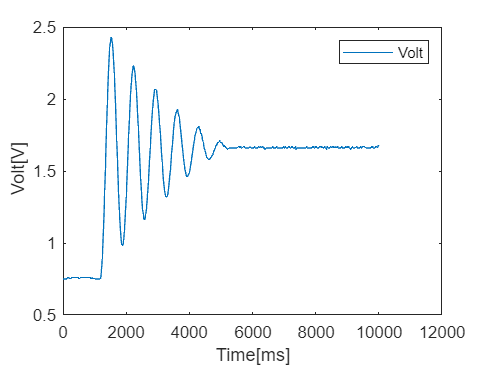


%Plots
%Voltageplot
plot(Time,A)
xlabel('Time[ms]')
ylabel(' Volt[V]')
legend('Volt')

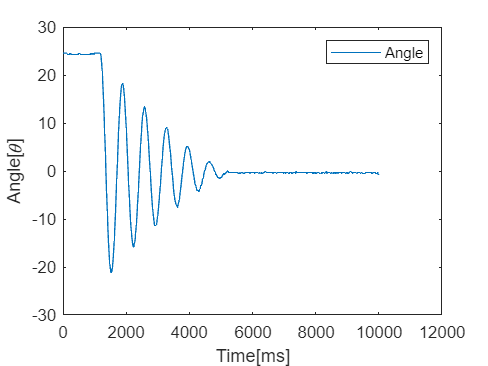

%Angleplot
plot(Time,VoltToAngle)
xlabel('Time[ms]')
ylabel('Angle[\theta]')
legend('Angle')

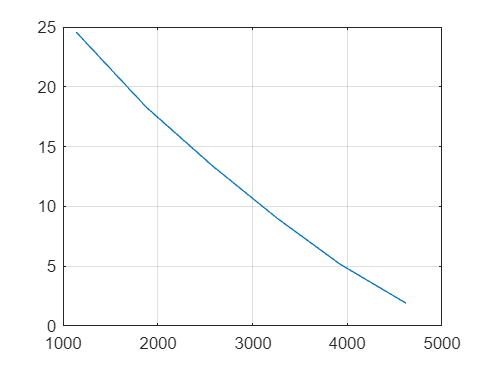



%Determining theta, epxonential decreasing tendency
%Datapoints at maximum angleshift
p= [24.55,18.2727,13.36,9,5.18,1.9];
%Time for said points
t= [1142,1882,2582,3262,3922,4622];

plot(t,p),grid

% CURVEFITTING - DONE
% General model Exp1:
%      f(x) = a*exp(b*x)
% Coefficients (with 95% confidence bounds):
%        a =       46.21  (32.8, 59.61)
%        b =  -0.0005215  (-0.0006717, -0.0003714)
% 
% Goodness of fit:
%   SSE: 9.571
%   R-square: 0.9731
%   Adjusted R-square: 0.9664
%   RMSE: 1.547

%Making the graph from curvefitter
alpha= 46.21;
beta= -0.0005215;
f = alpha*exp(beta*x)

$$f = \frac{4621\,{\mathrm{e}}^{-\frac{2404994258609883\,x}{4611686018427387904}}}{100}$$

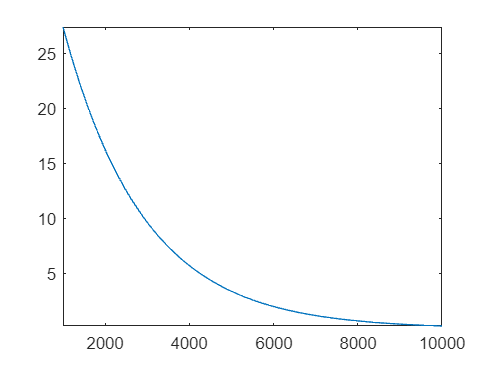


fplot(f,[1000 10000])


%The point is equal to 63% of max angle
24.55*0.63

ans = 15.4665

%This angle gives a time value equal to the reciprocal of sigma
sigma = 2098.791621;

%Making a new graph to see its tedency, using sigma
alpha= 1;
beta= -1/sigma;
f = alpha*exp(beta*x)

$$f = {\mathrm{e}}^{-\frac{2197305331450715\,x}{4611686018427387904}}$$

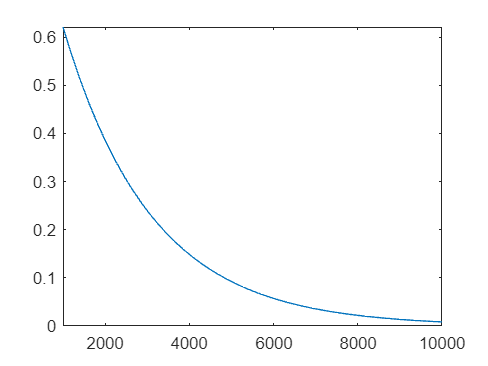

fplot(f,[1000 10000])



%Pulling the values from the maple document
m = 0.7493; %mass
g = 9.81; %gravitational acceleration
l = 0.09; %length from fulcrum to CoM
b =1.845975873*10^(-6); %dampening
Inertia = 0.001937159348; %inertia

%Checking to see if omega is correct from earlier
%Parting the function up into three parts
first = (m*g*l)/Inertia %first term

first = 341.5088

second = b/(2*Inertia) %second term

second = 4.7646e-04

%value for second term is so low it can actually be neglected. 
%may be a mistake from when calculating the dampening

omega = sqrt(first + second^2) %using them both in a squareroot

omega = 18.4800



%Transferfunction from transferfunctionTester.mlx
num = [0 1/Inertia] %numerator

num =          0  516.2198


den = [1^2 0 omega^2] %denominator

den =     1.0000         0  341.5088


G = tf(num,den) %Full form

G =
 
     516.2
  -----------
  s^2 + 341.5
 
Continuous-time transfer function.

